# Corrélation

## Accès dossier et choix essai

clear;
Type = 'DPMS0T';
Materiau = '7075';
Eprouvette ='3';
Numero = '1';
addpath('/home/tdelaselle/Documents/Codes/Codes-matlab/Fonctions');
repertoire_traitees = acces_donnees_traitees();
addpath(strcat(repertoire_traitees,'/',Type,'/',Materiau));
Naming = strcat(Type,'_',Materiau,'_',Eprouvette,'.',Numero);
load(strcat(Naming,'.mat'));

## Calcul

Paramètres

(Supprimer pré-trigger enlève 156 points)

pretrig = false;
if pretrig == 1
    init = 156;
else
    init = 1;
end
impul = 15360;
% Comptage du nombre de waveforms par channel
channel = HDD.CH;
ch1Nbre = 0;
for i = 1:size(channel)
    if channel(i) == 1
        ch1Nbre = ch1Nbre + 1;
    end
end
ch2Nbre = size(channel,1)-ch1Nbre;

len = size(WF);
for i = 2:ch1Nbre
    for j = (i+1):ch1Nbre
         [corr, t] = xcorr(WF.(strcat('1_',string(i)))(init:impul),WF.(strcat('1_',string(j)))(init:impul),'normalized');
         [Cor1(i,j), x] = max(corr);
         dt1(i,j) = t(x);
    end
end

for i = 2:ch2Nbre
    for j = (i+1):ch2Nbre
         [corr, t] = xcorr(WF.(strcat('2_',string(i)))(init:impul),WF.(strcat('2_',string(j)))(init:impul),'normalized');
         [Cor2(i,j), x] = max(corr);
         dt2(i,j) = t(x);
    end
end

## Affichage matrices

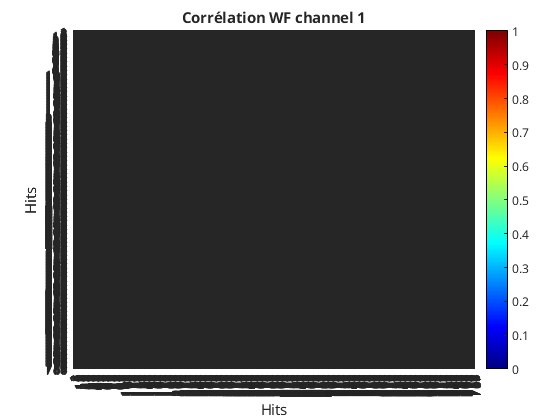

figure();
heatmap(Cor1);
colormap jet;
title(strcat('Corrélation WF channel 1'));
xlabel('Hits');
ylabel('Hits');
caxis([0 1]);

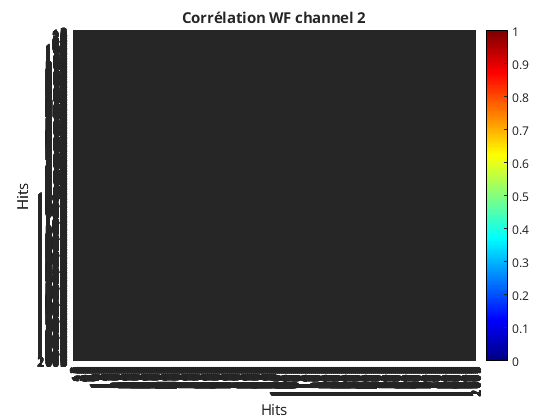

figure();
heatmap(Cor2);
colormap jet;
title(strcat('Corrélation WF channel 2'));
xlabel('Hits');
ylabel('Hits');
caxis([0 1]);

## Sauvegarde

repertoire_traitees = acces_donnees_traitees();
save(strcat('/home/tdelaselle/Documents/Données_essais/Traitement_essais/',Type,'/',Materiau,'/',Naming,'.mat'),"pretrig","impul","Cor1","Cor2","dt1","dt2",'-append');